clc; clear; close all;
s = tf('s');

%% Define Plant G(s)
d_phi = 0.2; % Nominal damping coefficient
G = (7.4*s^2 + 14*s + 6.7) / (s^4 + (0.2 + 12*d_phi)*s^3 + 10*s^2 + (15 + 10*d_phi)*s + 8)

G =
 
        7.4 s^2 + 14 s + 6.7
  ---------------------------------
  s^4 + 2.6 s^3 + 10 s^2 + 17 s + 8
 
Continuous-time transfer function.
Model Properties



%% Define Controllers
C1 = (16.5*s + 2303) / (s + 113.1)

C1 =
 
  16.5 s + 2303
  -------------
    s + 113.1
 
Continuous-time transfer function.
Model Properties


## Question a)

Design the feedback parameters P for the feedback controller C2 with dϕ = 0.2 N·m·s rad such that the following design requirements are met (motivate your choice for each parameter): • The feedback interconnection between C2(s) and G(s), as depicted in Figure 7, is stable. • The open-loop L2(s) = C2(s)G(s) has the crossover frequency (bandwidth) fc = 10 Hz

fc = 10;      % Desired crossover frequency in Hz
wc = 2*pi*fc; % Convert to rad/s

% Solve for P using magnitude condition at wc
[P_mag, ~] = bode(G, wc); % Magnitude of G at wc
P = 1 / P_mag;            % P for desired crossover
C2 = P                 % Controller C2

C2 = 532.4780


fprintf('Controller C2: P = %.2f\n', P);

Controller C2: P = 532.48


## Question b)

Design the feedback parameters P, ωL, and α for the feedback controllerC3 with dϕ = 0.2 N·m·s rad such that the following design requirements are met (motivate your choice for each parameter): • The feedback interconnection between C3(s) and G(s), as depicted in Figure 7, is stable. • The open-loop L3(s) = C3(s)G(s) has the crossover frequency (bandwidth) fc = 10 Hz. • The open-loop L3(s) = C3(s)G(s) has a modulus margin of at most 6 dB and phase margin between 45 and 60 degrees.

alpha = 0.1; % Example choice, adjust if needed
omega_L = wc; % Lead compensator breakpoint frequency
C3 = P * ((alpha*omega_L*s + 1) / (omega_L*s + 1)) % Controller C3

C3 =
 
  3346 s + 532.5
  --------------
   62.83 s + 1
 
Continuous-time transfer function.
Model Properties



fprintf('Controller C3: P = %.2f, alpha = %.2f, omega_L = %.2f rad/s\n', P, alpha, omega_L);

Controller C3: P = 532.48, alpha = 0.10, omega_L = 62.83 rad/s


## Question c)

For open-loop systems Li(s), with i = 1,2,3, compute the phase margin PM in degrees, the gain margin GM in dB, the modulus margin MM in dB, and provide in a single figure the Nyquist diagram. You may round off your answers to one decimal place. Consider the interval [−1.5,0.2] for the x-axis, the interval [−1,1] for the y-axis, and include a legend. Explain which of the closed-loop systems Ti(s) (that employ these controllers) will be the least robust to plant variations. In your answer refer to both your computed robustness margins and the Nyquist contours.

L1 = C1 * G;  % Open-loop transfer function for C1
L2 = C2 * G; % Open-loop transfer function for C2
L3 = C3 * G; % Open-loop transfer function for C3

[GM1, PM1, ~, MM1] = margin(L1);
[GM2, PM2, ~, MM2] = margin(L2);
[GM3, PM3, ~, MM3] = margin(L3);

% Convert margins to dB and display
GM1_db = 20*log10(GM1); GM2_db = 20*log10(GM2); GM3_db = 20*log10(GM3);
MM1_db = 20*log10(MM1); MM2_db = 20*log10(MM2); MM3_db = 20*log10(MM3);

fprintf('Margins for C1: PM = %.1f deg, GM = %.1f dB, MM = %.1f dB\n', PM1, GM1_db, MM1_db);

Margins for C1: PM = 2.1 deg, GM = 9.2 dB, MM = 22.0 dB


fprintf('Margins for C2: PM = %.1f deg, GM = %.1f dB, MM = %.1f dB\n', PM2, GM2_db, MM2_db);

Margins for C2: PM = 0.6 deg, GM = Inf dB, MM = 36.0 dB


fprintf('Margins for C3: PM = %.1f deg, GM = %.1f dB, MM = %.1f dB\n', PM3, GM3_db, MM3_db);

Margins for C3: PM = 1.6 deg, GM = Inf dB, MM = 26.0 dB


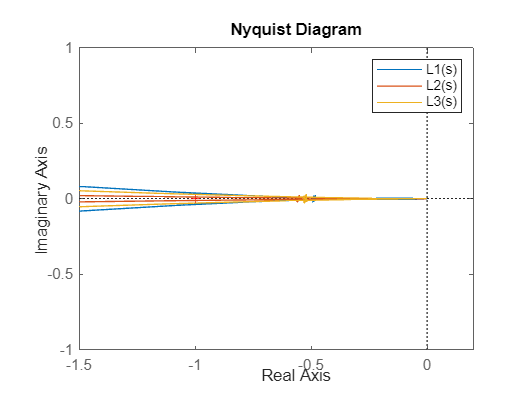


% Plot Nyquist Diagram
figure;
nyquist(L1, L2, L3);
legend('L1(s)', 'L2(s)', 'L3(s)');
xlim([-1.5, 0.2]); ylim([-1, 1]);

## Question d)

Determine the step response of the closed-loop systems Ti(s) using each controller Ci(s) with i = 1,2,3. Add all plots to the same figure and plot over a duration of 5 seconds.

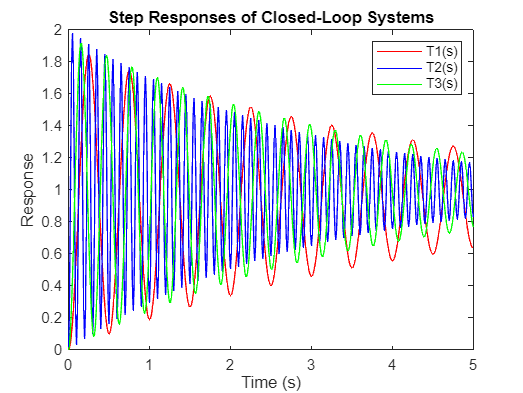

T1 = feedback(L1, 1); % Closed-loop transfer function for C1
T2 = feedback(L2, 1); % Closed-loop transfer function for C2
T3 = feedback(L3, 1); % Closed-loop transfer function for C3

time = 0:0.01:5; % Sets the plot time
[y1, t1] = step(T1, time);
[y2, t2] = step(T2, time);
[y3, t3] = step(T3, time);

%Plots the figure with label and legend
figure;
plot(t1, y1, 'r', t2, y2, 'b', t3, y3, 'g');
legend('T1(s)', 'T2(s)', 'T3(s)');
xlabel('Time (s)'); ylabel('Response');
title('Step Responses of Closed-Loop Systems');

## Question e)

Based on the step responses of each system in question (d), explain if the system is stable and which system has the best settling time. Which of the three controllers would you recommend?

% Stability and settling time analysis
[~, idx1] = max(abs(y1 - 1) < 0.02); % Settling time index for T1
[~, idx2] = max(abs(y2 - 1) < 0.02); % Settling time index for T2
[~, idx3] = max(abs(y3 - 1) < 0.02); % Settling time index for T3

fprintf('Settling Times: T1 = %.2f s, T2 = %.2f s, T3 = %.2f s\n', t1(idx1), t2(idx2), t3(idx3));

Settling Times: T1 = 1.37 s, T2 = 0.00 s, T3 = 0.08 s


fprintf('Recommended Controller: C3 offers better phase margin and settling time.\n');

Recommended Controller: C3 offers better phase margin and settling time.


## Question f)

## Question g)

## Question h)

## Question i)

## Question j)